# Prosthesis Mid-level Control.

## 1.a. Load the data

In this workbook, we will simulate an impedance-based finite state machine controller for a knee and ankle prosthesis.  We will largely follow the "Design and Control of a Powered Transfemoral Prosthesis" by Sup et al, 2008.  

The data this time includes Ankle and Knee moments (torques) calculated using specialized software.  Positive moments and velocites at the ankle are in dorsiflexion (same as last HW), and at the knee are in extension.

clear; close all; clc
addpath('MdlevelC_functions\','..\Sensor_data\')
file2load  = "0deg_1.2ms_data.mat"; % Load the intermediate walking speed trial
load(file2load);
head(D) % Show the top 8 rows of the data table (D)

       Time            R_COP               L_COP                       R_F                             L_F                            R_Accel                            R_Gyro                            L_Accel                          L_Gyro                R_Ankle_Angle    L_Ankle_Angle    R_Ankle_Velocity    L_Ankle_Velocity    R_Ankle_Moment    L_Ankle_Moment    R_Knee_Angle    L_Knee_Angle    R_Knee_Velocity    L_Knee_Velocity    R_Knee_Moment    L_Knee_Moment
    __________    ________________    ________________    _____________________________    _______

## 1.b Create a finite state machine

"GetGaitState" takes in **D**, the data table, and returns the gait state for the right leg only; then, run this cell to produce a plot of gait state vs time.  We will describe gait state as an integer 1-4, according to the following: 1: Early Stance ("Stance Flexion"), 2: Late Stance ("Pre-swing"), 3: Early Swing (Swing flexion), 4: Late Stance (Swing Extension).  You will need to use a for-loop to iterate through D.  The state machine is defined as follows:

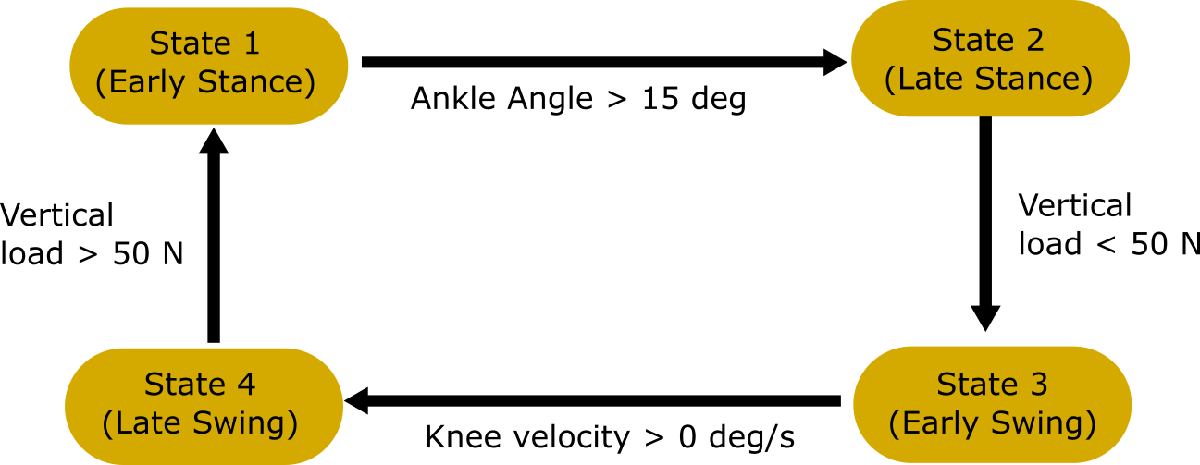

Assuming our "prosthesis" has encoders on the ankle and knee (thus angles and velocities can be measured), it can accurately produce the torque that we command, and that it can sense force with a load cell in the shank--we will use our force plate to emulate this load cell (e.g., use *D.R_F(:,3)*).

Note: Function keeps track of the current_state, and if/else conditions should check for both the current state and the heuristic we are checking.

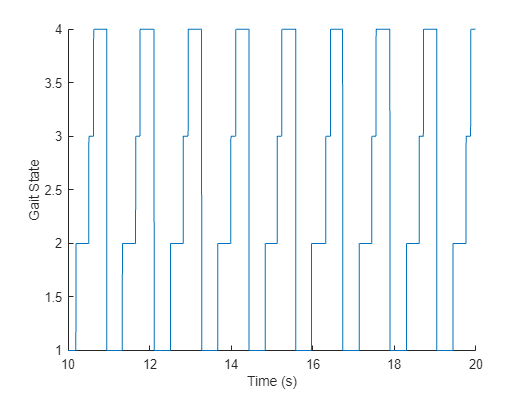

D.R_GaitState = GetGaitState(D);
figure; hold on
plot(D.Time, D.R_GaitState)
xlabel('Time (s)')
ylabel('Gait State') 
xlim([10,20])

## 1.c Identify transition criteria from plots

Using subplots to plot gait_state, ankle angle, knee angle, and vertical force for approximately ONE STRIDE. 

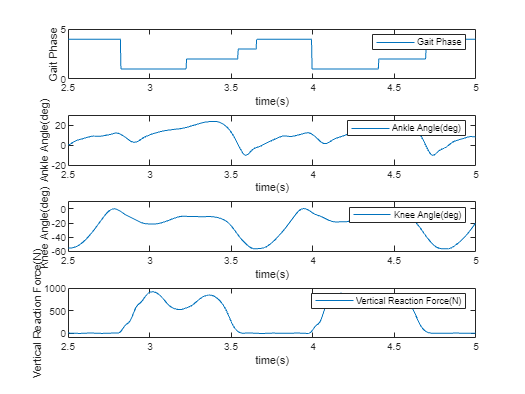

subplot(4,1,1)
plot(D.Time, D.R_GaitState)
xlim([2.5 5])
ylim([0 5])
xlabel("time(s)")
ylabel("Gait Phase")
legend("Gait Phase")

subplot(4,1,2)
plot(D.Time, D.R_Ankle_Angle)
xlim([2.5 5])
ylim([-20 30])
xlabel("time(s)")
ylabel("Ankle Angle(deg)")
legend("Ankle Angle(deg)")

subplot(4,1,3)
plot(D.Time, D.R_Knee_Angle)
xlim([2.5 5])
ylim([-60 10])
xlabel("time(s)")
ylabel("Knee Angle(deg)")
legend("Knee Angle(deg)")

subplot(4,1,4)
plot(D.Time, D.R_F(:,3))
xlim([2.5 5])
ylim([-100 1000])
xlabel("time(s)")
ylabel("Vertical Reaction Force(N)")
legend("Vertical Reaction Force(N)")

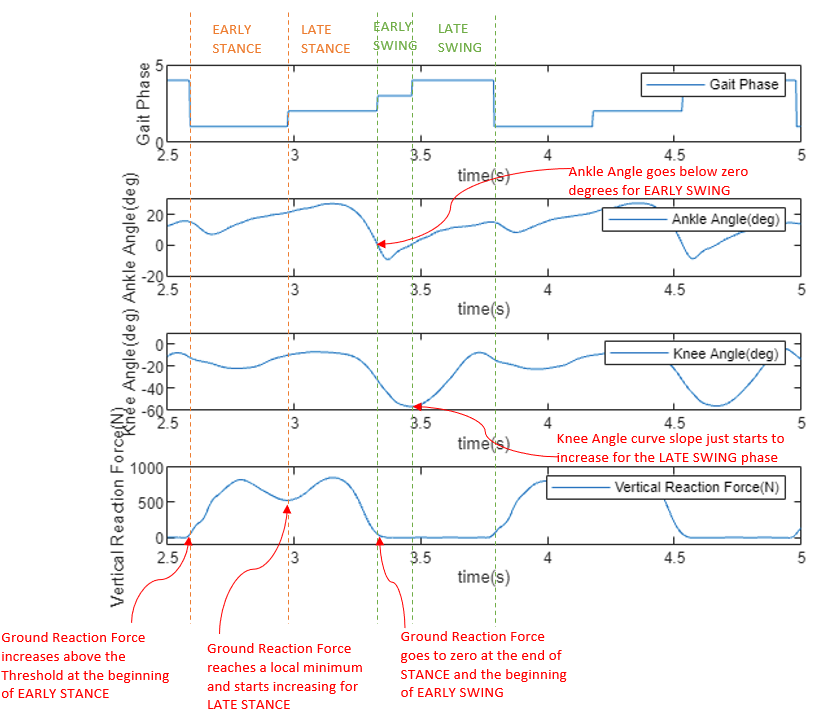

## 2.a: Develop Ankle Impedance Controller

Now that we have a working state machine, we can see how well spring-dampers can emulate the biological ankle torque for our participant.  The impedance parameters we will use are from Table 4 in the reading, which were fit to "Prototypical Gait."

**Modifying** "ImpedanceController.m" to take in controller_params, gait state, angle, and velocity, and return a vector for the actuator torque.  Usinf a for loop to iterate through the data, and use an if/else statement to get the correct stiffness, damping, and setpoint for the current state

*Note: *Sign convention is important again.  Let's keep our dorsiflexion moment and angle positive, and let's keep our stiffness and damping parameters positive, so we will need to multiply our actuator torque by -1 **inside** the ImpedanceController function to match our convention 

Note: plotted actuator torques will look opposite to the biological ankle moments.

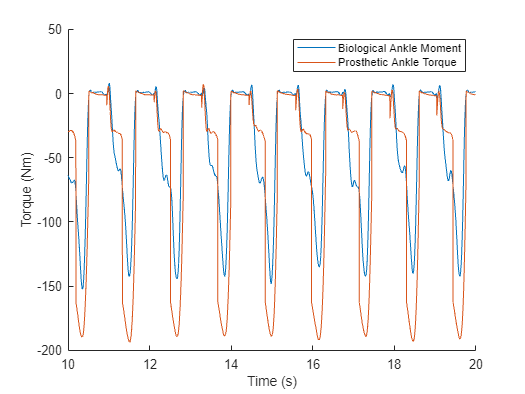

ankle_controller_params = ...
    [1.35, 4.50, 0.04, 0.134,...
    0.118, 5e-3, 3e-3, 2e-3,...
    -5, -18, 23, 2]; % These values taken from the paper

ankle_actuator_torque = ImpedanceController(ankle_controller_params, D.R_GaitState, D.R_Ankle_Angle, D.R_Ankle_Velocity);
figure; hold on
plot(D.Time, D.R_Ankle_Moment)
plot(D.Time, ankle_actuator_torque)
legend(["Biological Ankle Moment","Prosthetic Ankle Torque"])
xlabel('Time (s)')
ylabel('Torque (Nm)')
xlim([10,20])

## 2.b: Assess fit.

There are two common ways to describe the goodness of fit:  R-squared, and RMSE. Calculating both results for our impedance controller relative to the Biological Ankle Moment. 

RMSE_Ankle_Torque=fitlm(ankle_actuator_torque,D.R_Ankle_Moment)

RMSE_Ankle_Torque = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat       pValue   
                   ________    _________    _______    ___________

    (Intercept)    -9.4189       0.30699    -30.681    1.0576e-196
    x1             0.57592     0.0034486        167              0


Number of observations: 9001, Error degrees of freedom: 8999
Root Mean Squared Error: 23.4
R-squared: 0.756,  Adjusted R-Squared: 0.756
F-statistic vs. constant model: 2.79e+04, p-value = 0

***Questions and Answers******:***

*1) What is the RMSE?*

***A:*** ***The RMSE value for Ankle Torque with respect to Right Ankle Moment is 23.4 N-m.***

*2) What is the R-squared?*

***A: The R-squared value for Ankle Torque with respect to Right Ankle Moment is 0.756.***

*3) Look at Figure 10 in the reading.  The impedance parameters seem to do a much better job for them--why is that? *

***A: 1) The walking data across the population was extracted from the Winter(1991) research paper, which was scaled for a 75kg individual; and worked well theoretically.***

***    2) The prototype was designed and parameters were tuned to be run on the same data; hence, the controller works well for those conditions. ***

***    3) This can be deemed similar to the case of "Overfitting" a model, wherein the model (controller function here) works best for one set of data but would fail even if a parameter slightly changes.***

***    4) It can be seen that their own subsequent analysis with an able-bodied tester required new set of parameters for the following reasons:***

***        a) As each individual would have different built, weight, gait, cadence, etc., they would require separate individual tuning for the controller; as opposed to the averaged data. ***

***        b) Mechanical joints could have some inherent damping; hence would require less damping as estimated by the controller and the function would not converge.***

***        c) There could be inherent discrepancies in the data dependent on noise, feedback delays, filtering techniques amongst other things.***

***    5) The issues mentioned above are also the reasons why the parameters do not work as appropriately with our data as well. ***

## 2.c: Knee impedance controller

**Perform the same analysis for the knee.**  Using Table 4 from the reading to get the impedance parameters (ignore the k2 column).  Plottingthe biological knee moment and prosthetic knee torque (similar to above), from time T = 10s to 20s. Calculating RMSE and R-squared for the knee.

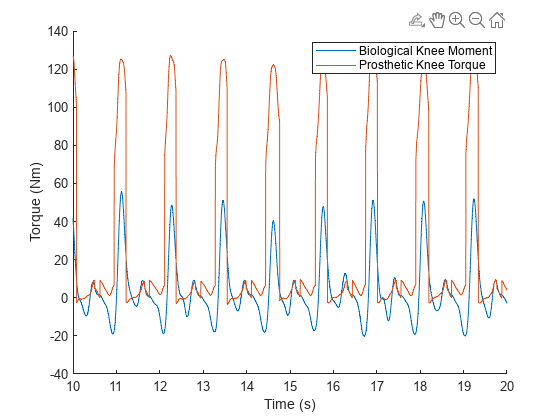

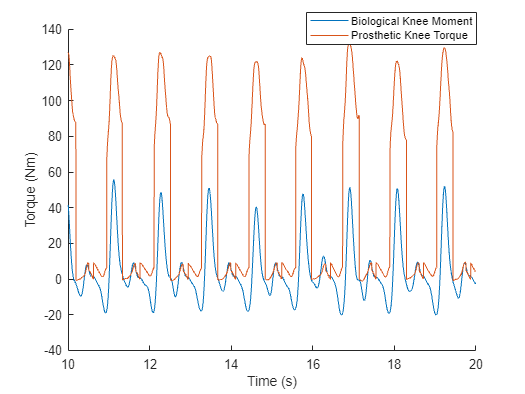

knee_controller_params = ...
    [3.78, 0.0, 0.0, 0.093,...
    0.025, 0.03, 0.016, 0.013,...
    12, 37, 52, 44]; % These values taken from the paper

knee_actuator_torque = ImpedanceController(knee_controller_params, D.R_GaitState, D.R_Knee_Angle, D.R_Knee_Velocity);
figure; hold on
plot(D.Time, D.R_Knee_Moment)
plot(D.Time, knee_actuator_torque)
legend(["Biological Knee Moment","Prosthetic Knee Torque"])
xlabel('Time (s)')
ylabel('Torque (Nm)')
xlim([10,20])

legend("Position", [0.58488,0.88675,0.32321,0.082143])

RMSE_Knee_Torque=fitlm(knee_actuator_torque,D.R_Knee_Moment)

RMSE_Knee_Torque = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat       pValue   
                   ________    _________    _______    ___________

    (Intercept)    -6.0496       0.15963    -37.898    1.0063e-291
    x1             0.24163     0.0025164     96.022              0


Number of observations: 9001, Error degrees of freedom: 8999
Root Mean Squared Error: 11.9
R-squared: 0.506,  Adjusted R-Squared: 0.506
F-statistic vs. constant model: 9.22e+03, p-value = 0

***Questions******:***

*1) What is the RMSE?*

***A:*** ***The RMSE value for Knee Torque with respect to Right Knee Moment is 11.9 N-m.***

*2) What is the R-squared?*

***A:*** ***The R-squared value for Knee Torque with respect to Right Knee Moment is 0.506.***

## 3.a: Optimize Impedance Parameters

In this section, we will use optimization to determine the best impedance parameters for our subject.  The goal is to find the impedance parameters that minimize error between the actuator torque and the biological moment. 

"ImpedanceControlCostFunction.m", which is our custom cost function used by the optimization. This cost function takes in a set of impedance parameters provided by the optimization ("impedance_params_to_evaluate") as well as gait state, joint angle, joint velocity, and joint biological torque, which are needed to calculate actuator torque. Our goal within this cost function is to 1) calculate actuator torque based on the passed impedance parameters, and 2) calculate the RMSE ("error") between actuator torque and biological moment to pass back to the optimization algorithm and drive the gradient descent. 

When run, the optimization algorithm iteratively passes specificed cost function a new batch of parameters to try. In the *fmincon* code below, the variable we are optimizing over is represented by "x". In the cost function, you will see this variable is specified as "impedance_params_to_evaluate" variable.

%Do not modify this cell
lb = [0, 0, 0, 0, 0, 0, 0, 0, -100, -100, -100, -100]; % lower bounds for the 12 parameters
ub = [100, 100, 100, 100, 100, 100, 100,100, 100, 100, 100,100]; % upper bounds for the 12 parameters

opt_impedance_params_ankle = fmincon(@(x)ImpedanceControlCostFunction(x, ...
    D.R_GaitState, D.R_Ankle_Angle, D.R_Ankle_Velocity, D.R_Ankle_Moment), ...
    ankle_controller_params,[],[],[],[], lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


opt_impedance_params_knee = fmincon(@(x)ImpedanceControlCostFunction(x, ...
    D.R_GaitState, D.R_Knee_Angle, D.R_Ankle_Velocity, D.R_Knee_Moment), ...
    knee_controller_params,[],[],[],[], lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


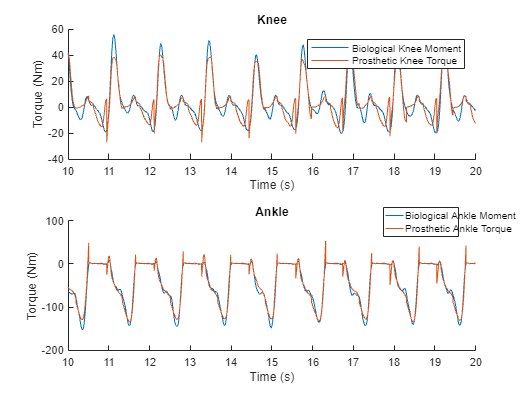

ankle_actuator_torque = ImpedanceController(opt_impedance_params_ankle, D.R_GaitState, D.R_Ankle_Angle, D.R_Ankle_Velocity);
actuator_torque_knee = ImpedanceController(opt_impedance_params_knee, D.R_GaitState, D.R_Knee_Angle, D.R_Knee_Velocity);

tiledlayout(2,1)
ax1 = nexttile; 
hold on
plot(D.Time, D.R_Knee_Moment)
plot(D.Time, actuator_torque_knee)
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Knee')
legend(["Biological Knee Moment","Prosthetic Knee Torque"])
xlim([10,20])

ax2 = nexttile; 
hold on
plot(D.Time, D.R_Ankle_Moment)
plot(D.Time, ankle_actuator_torque)
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Ankle')
legend(["Biological Ankle Moment","Prosthetic Ankle Torque"])
xlim([10,20])
% axes 1
legend("Position", [0.65708,0.91937,0.3,0.072619])
% axes 2
legend("Position", [0.73202,0.40072,0.14107,0.072619]) 

T_ankle=ImpedanceController(opt_impedance_params_ankle,D.R_GaitState,D.R_Ankle_Angle,D.R_Ankle_Velocity);
T_knee=ImpedanceController(opt_impedance_params_knee,D.R_GaitState,D.R_Knee_Angle,D.R_Knee_Velocity);
%RMSE_ankle = rmse(T_ankle, D.R_Ankle_Moment) not used
fitlm_ankle_RMSE = fitlm(T_ankle, D.R_Ankle_Moment).RMSE

fitlm_ankle_RMSE = 8.5301

%RMSE_knee = rmse(T_knee, D.R_Knee_Moment) not used
fitlm_knee_RMSE = fitlm(T_knee, D.R_Knee_Moment).RMSE

fitlm_knee_RMSE = 8.1027

***Questions****:*

*1) What is the RMSE for the ankle? [2]*

***A:*** ***The RMSE value for Ankle Torque with respect to Right Knee Moment  for optimized parameters is 8.53 N-m. ***

*What is the RMSE for the knee? [2]*

***A:*** ***The RMSE value for Knee Torque with respect to Right Knee Moment  for optimized parameters is 8.1 N-m.***

## 3.b: Try LG-walking impedance parameters for ramp ascent

We just found the optimal impedance parameters that replicate biological torque for this subject, and for the task of level ground walking.  A big question is whether we need different impedance parameters for different tasks. In this block, Code Block added to workspace as a new Table:** D_RA** (RA = ramp ascent). 

**This code block**: 

1) Applies existing state machine to this new ramp ascent data set using function GetGaitState(...). 

2) Applies existing impedance controller to this new ramp ascent data using your function ImpedanceController(...). Use the optimized knee and ankle impedance parameters calculated for level ground walking in Parts 2a and 2c. 

3) Plots the knee and ankle biological moments and prosthesis torques vs. time (you have code for this already in previous sections). 

4) Calculates the RMSE

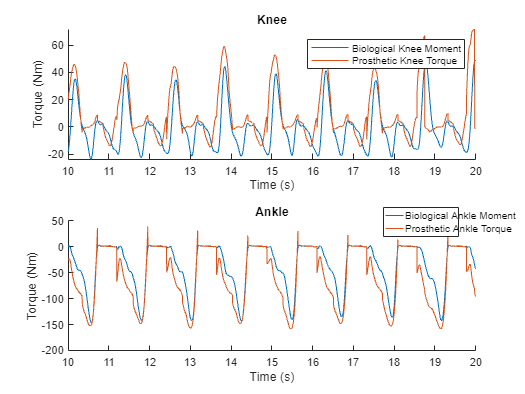

file2load  = "6deg_1.2ms_HW4.mat"; % Load the intermediate walking speed trial
D_tmp = load(file2load);
D_RA = D_tmp.D; 

RA_GaitState = GetGaitState(D_RA);
RA_ankle_actuator_torque = ImpedanceController(opt_impedance_params_ankle,RA_GaitState,D_RA.R_Ankle_Angle, D_RA.R_Ankle_Velocity);
RA_knee_actuator_torque = ImpedanceController(opt_impedance_params_knee,RA_GaitState,D_RA.R_Knee_Angle, D_RA.R_Knee_Velocity);

tiledlayout(2,1)
ax1 = nexttile; 
hold on
plot(D.Time, D_RA.R_Knee_Moment)
plot(D.Time, RA_knee_actuator_torque)
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Knee')
legend(["Biological Knee Moment","Prosthetic Knee Torque"])
xlim([10,20])

ax2 = nexttile; 
hold on
plot(D.Time, D_RA.R_Ankle_Moment)
plot(D.Time, RA_ankle_actuator_torque)
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Ankle')
legend(["Biological Ankle Moment","Prosthetic Ankle Torque"])
xlim([10,20])
% axes 1
legend("Position", [0.65708,0.91937,0.3,0.072619])
% axes 2
legend("Position", [0.73202,0.40072,0.14107,0.072619])

RA_fitlm_ankle_RMSE = rmse(RA_ankle_actuator_torque, D_RA.R_Ankle_Moment)

RA_fitlm_ankle_RMSE = 30.0354

RA_fitlm_knee_RMSE = rmse(RA_knee_actuator_torque, D_RA.R_Knee_Moment)

RA_fitlm_knee_RMSE = 17.3537

***Questions and Answers:***

*1) What is the RMSE for the knee and ankle, and how does it compare to the task the parameters were optimized for? [2]*

***A:*** ***1)*** ***The RMSE value for Knee Torque with respect to Right Knee Moment for optimized parameters for 6 degree Ramp Ascent angle is 30.035 N-m.***

***     2)*** ***The RMSE value for Ankle Torque with respect to Right Ankle Moment for optimized parameters for 6 degree Ramp Ascent angle is 17.3537 N-m.***

## 4) High-Level Mode Classification

### OVERVIEW: 

The purpose of this section is to build a high level classifier (using linear discriminant analysis, LDA) to identify if someone is about to take a step on level ground, or at an incline or decline. As seen in Section 3b, the impedance parameters for a given gait mode don't translate well to other modes. So each gait mode (level walking, incline walking, decline walking) requires ts own state machine with its own unique transition criteria and impedance parameters. One can imagine a multi-mode state machine might look something like this: 

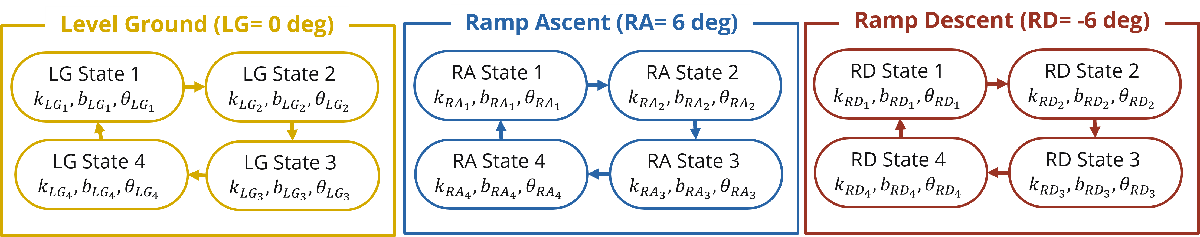

**The key takeaway here: it is really important that we know what ambulation mode (LG, RA, RD) the person is in so that we can appropriately control the prosthesis. It is also important that we know this information BEFORE they put their foot on the ground (heel strike). The prosthesis will need to behave differently beginning at heel strike, depending on the chosen ambulation mode. **

We will simulate this behavior by using the data collected in the lab. We have three files that are approximately 30 s each; one of someone walking at 0 deg, one at -6 deg (decline walking) and one at 6 deg (incline walking). 

### Load and arrange the new data 

Organize this data into an easy-to-use matrix, **D_all. **Notice that the data from all three files have been concatentated one after another. A new variable, **D_all.RampAngle**, tells us which samples belong to which file. Examine the output of the table to see this new column at the end. 

files2load  = ["neg6deg_1.2ms_data.mat", "0deg_1.2ms_data.mat", "6deg_1.2ms_data.mat"];
ramp_angles = [-6, 0, 6];
D_all = [];

for file_idx = 1:length(files2load)
    load(files2load(file_idx));
    D.RampAngle(:) = ramp_angles(file_idx); % Add a new column containing the ramp angle
    D_all = [D_all; D]; %Concatenate to make one long Data table with all three trials.
end
head(D_all); 

       Time            R_COP               L_COP                     R_F                              L_F                              R_Accel                          R_Gyro                           L_Accel                           L_Gyro               R_Ankle_Angle    L_Ankle_Angle    R_Ankle_Velocity    L_Ankle_Velocity    R_Ankle_Moment    L_Ankle_Moment    R_Knee_Angle    L_Knee_Angle    R_Knee_Velocity    L_Knee_Velocity    R_Knee_Moment    L_Knee_Moment    RampAngle
    __________    ________________    ________________    __________________________

## 4.a High Level Mode Classification

Once the foot is flat on the ground, IMUs are quite good at determing ground angle with simple analytical techniques, but we want to know the ground angle just before heel strike to change our early stance impedance parameters appropriately, before the foot has even touched the ground.  To do this, we will train a Linear Discriminant Analysis model. In our first attempt, we will train the LDA on instantaneous data from the accelerometer for all of the timepoints in our dataset that are 20 frames **before** heel strike (78 instances).

Note: we are using data from a non-amputee, but the hope is that if the prosthetic leg behaves adequately similarly during swing, this classifier would work with a prosthesis too. 

Plot below shows the predicted classes for all 78 exemplars, plotted on top of the actual classes. We will also generate a confusion matrix that shows the relationship between predicted class and actual class.

HS_indices = GetHeelStrikesKey(D_all.R_F(:,3));
just_before_HS_indices = HS_indices-20; % we need to predict 20 samples earlier than heel strike
[Samples, Labels] = GetAccelAtIndex(just_before_HS_indices, D_all);

disp(['Size of Sample Matrix: ' num2str(size(Samples))]); 

Size of Sample Matrix: 78   3


disp(['Size of Labels Matrix: ' num2str(size(Labels))]); 

Size of Labels Matrix: 78   1


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Delta |        Gamma |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.65385 |    0.046332 |     0.65385 |     0.65385 |       169.62 |      0.55682 |
|    2 | Best   |     0.47436 |    0.040691 |     0.47436 |     0.48392 |   2.1661e-05 |      0.99983 |
|    3 | Best   |     0.42308 |    0.037091 |     0.42308 |      0.4321 |     0.015065 |      0.07303 |
|    4 | Accept |     0.65385 |    0.036966 |     0.42308 |      0.4231 |       568.96 |    0.0074993 |
|    5 | Accept |     0.42308 |    0.040053 |     0.42308 |     0.42307 |    0.0016667 |     0.031638 |
|    6 | Accept |     0.42308 |    0.038065 |     0.42308 |     

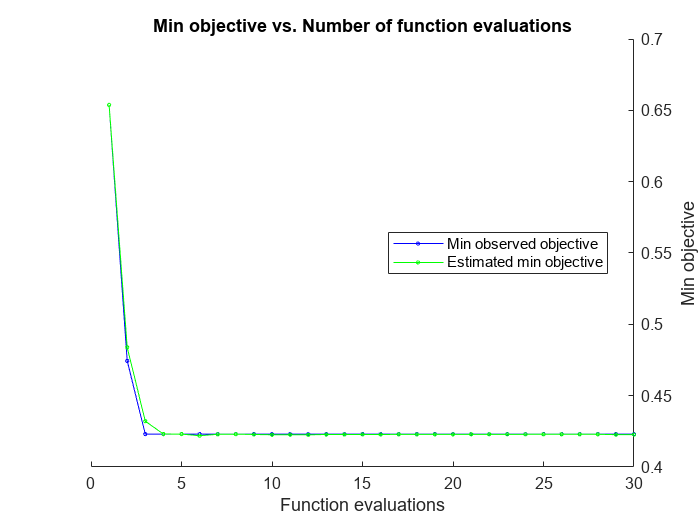

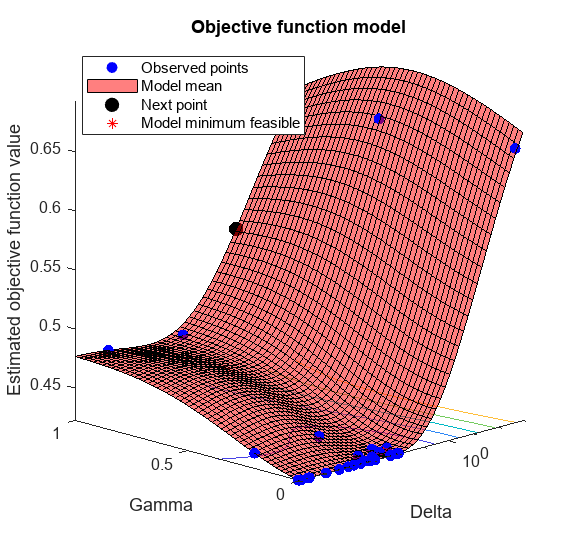


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 14.3716 seconds
Total objective function evaluation time: 1.2755

Best observed feasible point:
     Delta       Gamma 
    ________    _______

    0.015065    0.07303

Observed objective function value = 0.42308
Estimated objective function value = 0.42329
Function evaluation time = 0.037091

Best estimated feasible point (according to models):
      Delta       Gamma  
    _________    ________

    0.0051318    0.052868

Estimated objective function value = 0.42267
Estimated function evaluation time = 0.042143



mdl = fitcdiscr(Samples,Labels,'OptimizeHyperparameters','auto');  % add the correct inputs to fitcdiscr()!

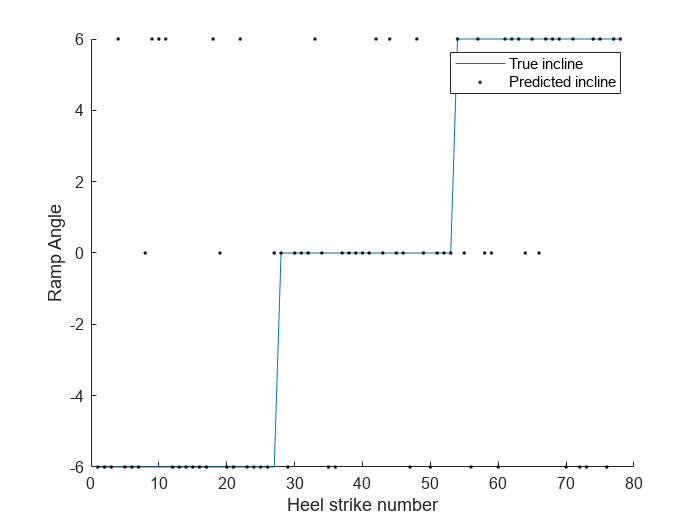

Predicted_Incline = predict(mdl, Samples);

figure; hold on
plot(Labels)
plot(Predicted_Incline,'k.',markersize=5)
xlabel('Heel strike number')
ylabel('Ramp Angle')
legend(["True incline", "Predicted incline"])

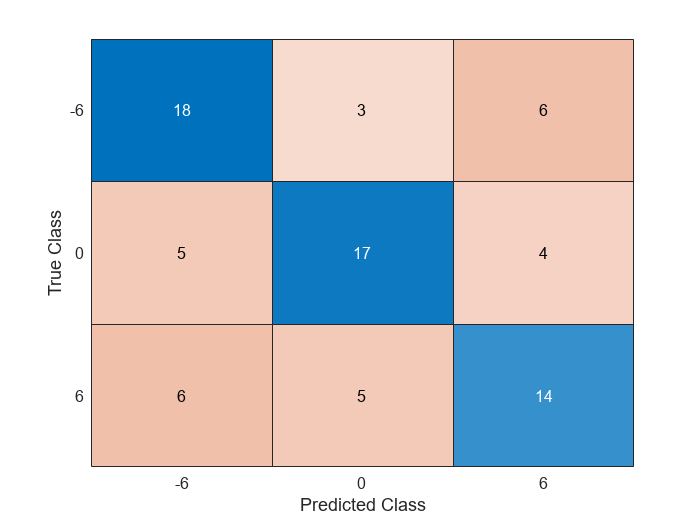

C = confusionmat(Labels,Predicted_Incline,'order',[-6 0 6]);
figure; confusionchart(C,{'-6', '0', '6'});

***Questions and Answers****:*

*1) Why might instantaneous values from the IMU have been a poor predictor of ramp angle?  [5]*

**A:** **1)** **The instantaneous values may be subject to noise, signal bias or may be in general be an outlier, which could affect the prediction drastically. **

**     2) Additionally, it is important to know when the motion would have occured during the gait phase.**

**     3) Every gait phase and stride might be slightly different, hence it is better to predict it in a set of data rather than an individual value.**

**     4) Also, a single value maybe subject to overshoot where the gain tuning might not be proper, and one set of parameters could not provide the best fit of model to data.**

*2) Other than time-history information from the IMU (which we'll discuss in 4.b), what other sensors do you suspect could have been helpful and why? [5]*

**A:** **1) A pressure sensor in the sole of the shoes could tell how the center of pressure moves forward or backward, which can be combined with another parameters to detect the ramp ascent.**

    ** 2) Other than the time history, an ultrasonic(radar) sensor or a lidar sensor could have bee used to predict the distance between the foot base and the ground, if the location of mounting on the limb would be known precisely. **

**     3) A filtering algorithm to discard the outliers like the Bayesian filtering, Kalman filter would help discard outliers from the data to get better predictions.**

**     4) A set of interdependent parameters and their correlation with the desired phase would help yield better results.**

*3) According to the confusion matrix you generated above, what is the classification acccuracy and classification error for Ramp Ascent? [2]*

**A:** **1)** **The classification accuracy of Ramp Ascent is 14/25 i.e. 56%.**

**     2) The classification error for Ramp Ascent is 21/78 i.e. 26.92%.**

*4) According to the confusion matrix you generated above, what is the classification acccuracy and classification error for Level Ground Walking? [2]*

**A:** **1)** **The classification accuracy for Level Ground Walking is 17/26 i.e. 65.38%.**

**2) The classification error for Level Ground Walking is 19/78 i.e. 23.07%.**

## 4.b Feature Engineering

The instantaneous values did a fairly poor job of predicting ramp angle.  But we aren't making good use of data prior to the moment we make our prediction.  To do this in an efficent way, we will look at a window of data preceding heel strike (100 samples), and use features of this data: the max, mean, and min. 

**GetFeatures.m** takes in the indices of interest (just_before_heel_strike_indices), window size, the data Table D_all, and a list of strings specifying the signalsToUse, and returns two variables: a matrix (#heel_strikes x 9) containing the mean, max and min for each of the three Acceleromater channels, and the Labels (ramp angle) for the corresponding heel strikes.

signalsToUse = ["R_Accel","RampAngle"];
windowSize = 100;
[SamplesWithFeatures, Labels] = GetFeatures(just_before_HS_indices, windowSize, D_all, signalsToUse);

% Create a linear model
mdl = fitcdiscr(SamplesWithFeatures, Labels);

Error using classreg.learning.classif.FullClassificationModel.prepareData
No class names are found in input labels.

Error in classreg.learning.FitTemplate/fit (line 246)
                    this.PrepareData(X,Y,this.BaseFitObjectArgs{:});

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('ClassificationDiscriminant.fit', 'C:\Program Files\MATLAB\R2022b\toolbox\stats\classreg\ClassificationDiscriminant.m', 107)" style="font-weight:b

Predicted_Incline = predict(mdl, SamplesWithFeatures);

figure; hold on
plot(Labels)
plot(Predicted_Incline,'k.',markersize=5)
xlabel('Heel strike number')
ylabel('Ramp Angle')
legend(["True incline", "Predicted incline"])
C = confusionmat(Labels,Predicted_Incline,'order',[-6 0 6]);
figure; confusionchart(C,{'-6', '0', '6'}); 